# Tutorial 6 -- Symbolic

## The MIDI Toolbox

### setting the Matlab path

Start by setting a path to the folder containing the MIDI Toolbox, which contains all of the functions we'll be using here.

addpath(genpath('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_06_symbolic\2share\code\1.1-master'))

### consulting the manual

First, consult the manual! (If you get an error message here, just open the pdf files without Matlab's help.)

cd('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_06_symbolic\2share\code\1.1-master\1.1-master\documentation')
system('MIDItoolbox1.1_manual.pdf &');

### asking for help

We can also learn about the MIR Toolbox's many functions from within Matlab itself by using the help function.

help miditoolbox

  MIDItoolbox
  Version 1.1 18-May-2016
  
  A more detailed documentation of each function is available using the
  help command. For instance, type help tempocurve.
 
  A complete documentation is available online.
 			http://github/miditoolbox/
 
 CONVERSION FUNCTIONS
  dir2coll       - Converts a directory of MIDI files to cellmatrix structure
  hz2midi        - Convert frequencies to MIDI numbers
  keyname        - Convert keys (24) to key names (text)
  midi2hz        - Convert MIDI note numbers to frequencies (Herz)
  notename       - Convert MIDI numbers to American pitch spelling (text)
  readmidi       - Reads a MIDI file to a notema

## Import

### reading files

#### readmidi

Let's open a file! This example is from the Haydn data set that I created back in 2017. You can learn more about it here: [https://www.tandfonline.com/doi/suppl/10.1080/09298215.2017.1367010?scroll=top](https://www.tandfonline.com/doi/suppl/10.1080/09298215.2017.1367010?scroll=top)

cd('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_06_symbolic\2share\data\haydn_midi')
haydn = readmidi('haydn_op017_no01_mv01_1727.mid');
haydn = sortrows(haydn,[1 3]); % readmidi doesn't sort rows by voice.
haydn(:,3) = haydn(:,3)+1; % miditoolbox ignores channels that equal 0

Let's look at the first 10 rows of the note matrix. Refer to the manual to understand what these columns represent.

haydn(1:10,:)

ans =     4.5000    0.5000    1.0000   64.0000   64.0000    2.1000    0.3000
    5.0000    0.5000    1.0000   68.0000   64.0000    2.4000    0.3000
    5.0000    1.0000    2.0000   59.0000   64.0000    2.4000    0.6000
    5.0000    1.0000    3.0000   52.0000   64.0000    2.4000    0.6000
    5.0000    1.0000    4.0000   40.0000   64.0000    2.4000    0.6000
    5.5000    0.5000    1.0000   71.0000   64.0000    2.7000    0.3000
    6.0000    0.5000    1.0000   69.0000   64.0000    3.0000    0.3000
    6.0000    1.0000    2.0000   63.0000   64.0000    3.0000    0.6000
    6.0000    1.0000    3.0000   57.0000   64.0000    3.0000    0.6000
    6.0000    1.0000    4.0000   47.0000   64.0000    3.0000    0.6000


Let's import a file from the NES data set. You can learn more about it here: [https://github.com/chrisdonahue/nesmdb#nesmdb-package-information](https://github.com/chrisdonahue/nesmdb#nesmdb-package-information)

cd('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_06_symbolic\2share\data\nesmdb_midi\nesmdb_midi\test')
nes = readmidi('002_1943_TheBattleofMidway_00_01Title.mid');
nes = sortrows(nes,[1 3]); % readmidi doesn't sort rows by voice.
nes(:,3) = nes(:,3)+1; % miditoolbox ignores channels that equal 0

#### playsound

Play the first 50 notes from the Haydn excerpt using fm synthesis.

playsound(haydn(1:50,:),'fm');

83.6K samples


And the NES tune?

playsound(nes,'fm');

157.1K samples


Get a sense of the game and its title music here: [https://www.youtube.com/watch?v=CsYD_lUn090](https://www.youtube.com/watch?v=CsYD_lUn090)

## Visualization

#### pianoroll

The piano roll is one of the most common visual representations of music. Its history is fascinating. Here's an example: [https://www.youtube.com/watch?v=ZXYslYDzF8o](https://www.youtube.com/watch?v=ZXYslYDzF8o)

Let's look at a piano roll of the first 50 events from the Haydn excerpt.

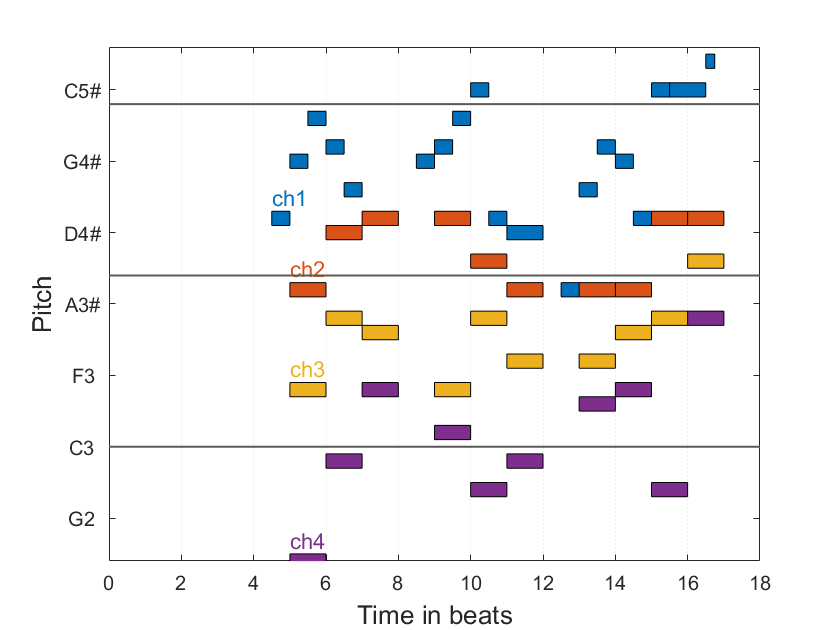

figure; pianoroll(haydn(1:50,:))

And the NES example?

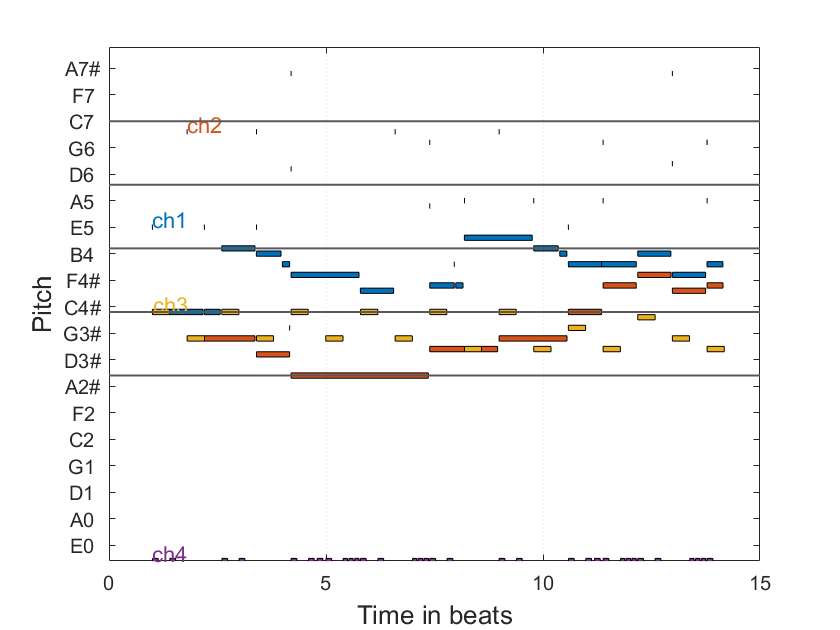

figure; pianoroll(nes(1:100,:));

#### extracting parts

Let's just look at the first violin part from the Haydne example. We'll store it in the variable 'vln1'.

vln1 = getmidich(haydn,1);

#### ismonophonic

Sanity check: Is the channel monophonic? (String parts can contain extended string techniques like double stops.)

ismonophonic(vln1)

ans = 1

#### plotmelcontour

Let's plot the melodic contour of the first 100 events in the first violin. We can do it at any resolution, so I'll plot the contour at a resolution of 1 beat and 5 beats.

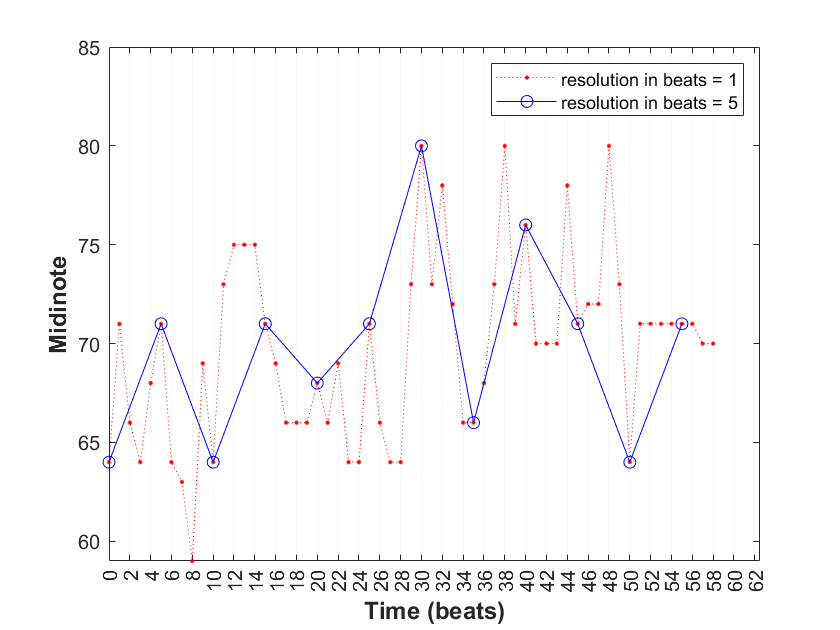

vln1 = vln1(1:100,:); % just look at first 100 events.
figure; plotmelcontour(vln1,1,'abs',':r.')
hold on
plotmelcontour(vln1,5,'abs','-bo')
legend(['resolution in beats = 1'; 'resolution in beats = 5'])

#### durdist1

Now let's plot a distribution of all of the rhythmic durations in the Haydn example.

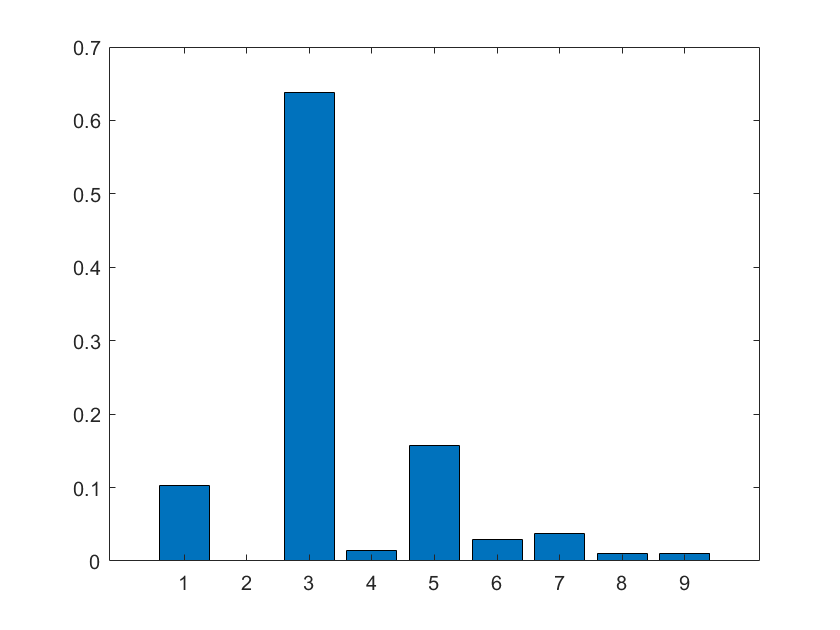

dur = durdist1(haydn);
figure; bar(dur)

#### plotdist

Use the 'plotdist' function to get axis labels!

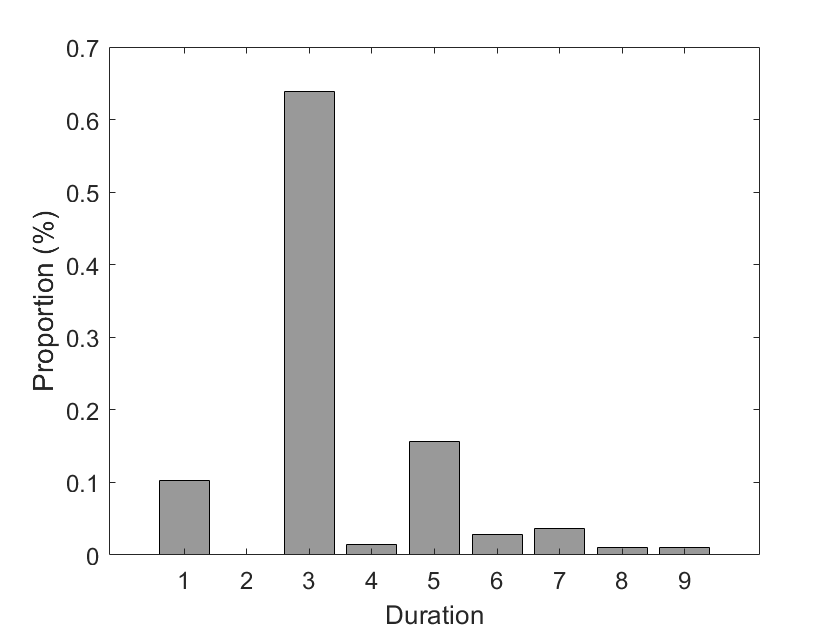

figure; plotdist(durdist1(haydn));

#### durdist2

Now we can plot a distribution of all the duration transitions within the first violin part (i.e., from one duration to the next).

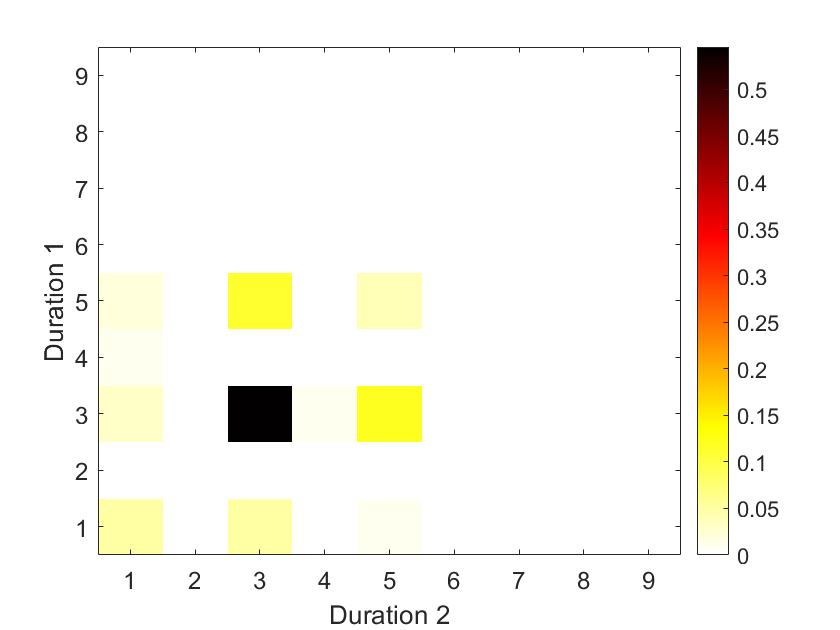

figure; plotdist(durdist2(vln1),'hot');

#### Other distribution plots

Next, let's look at a pitch-class distribution, or a pitch-class transition matrix, or an interval distribution, or an interval distribution transition matrix! So many options!

Can you discern the key from the pitch-class distribution?

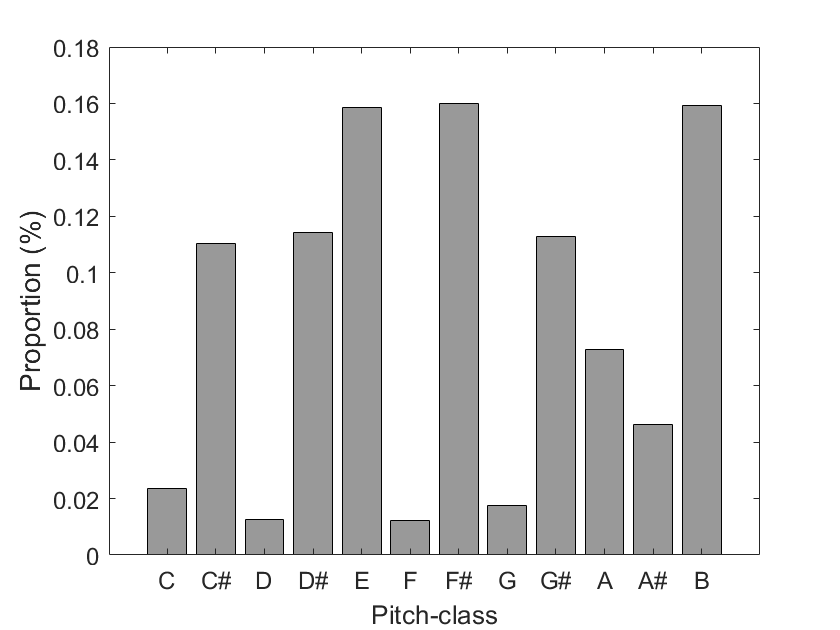

figure; plotdist(pcdist1(haydn)); 

Here is a plot of the PC-to-PC transitions in the first violin.

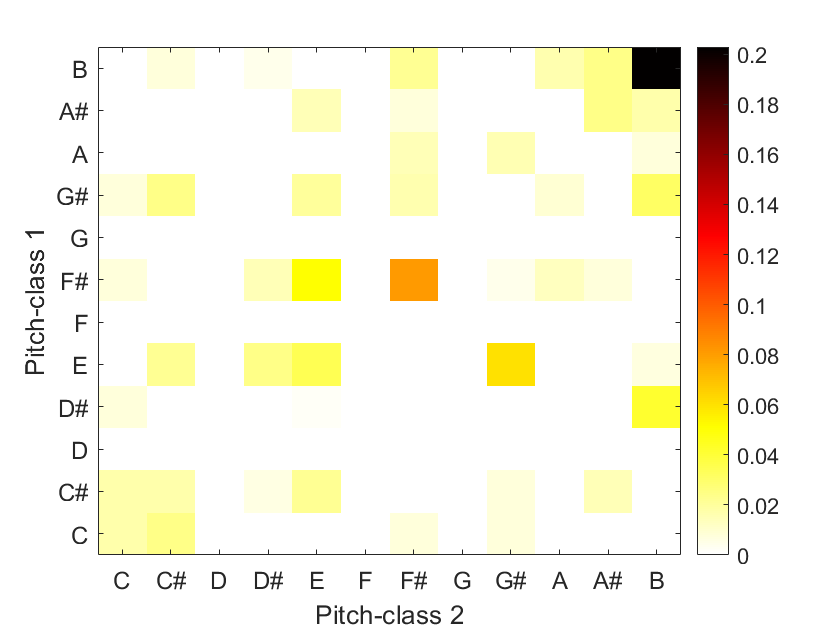

figure; plotdist(pcdist2(vln1),'hot');  

We can also plot the distribution of intervals in the first violin part.

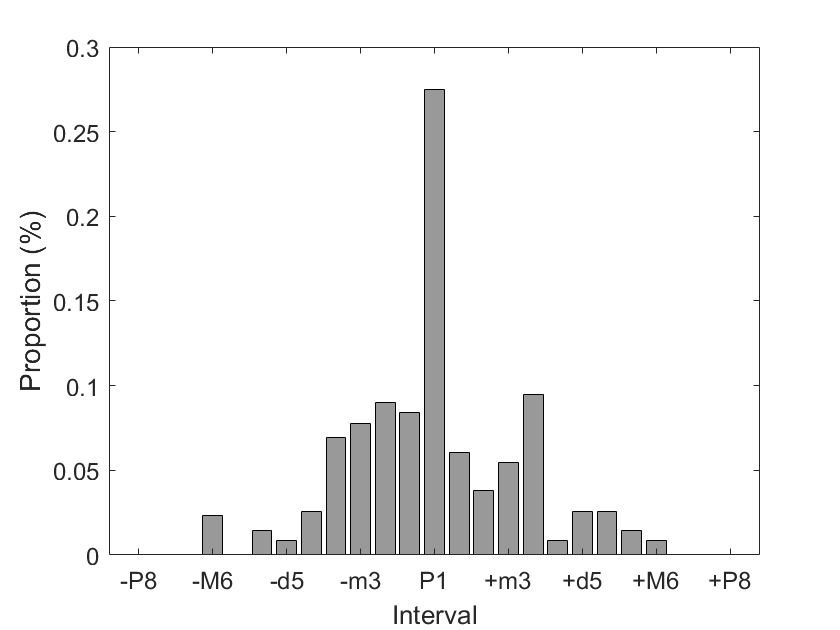

figure; plotdist(ivdist1(vln1)); 

iv = ivdist1(vln1)

iv =          0         0         0    0.0232         0    0.0146    0.0086    0.0258    0.0694    0.0775    0.0898    0.0840    0.2751    0.0607    0.0378    0.0548    0.0950    0.0086    0.0258    0.0258    0.0146    0.0086         0         0         0


Finally, let's visualize the interval transitions in the first violin part.

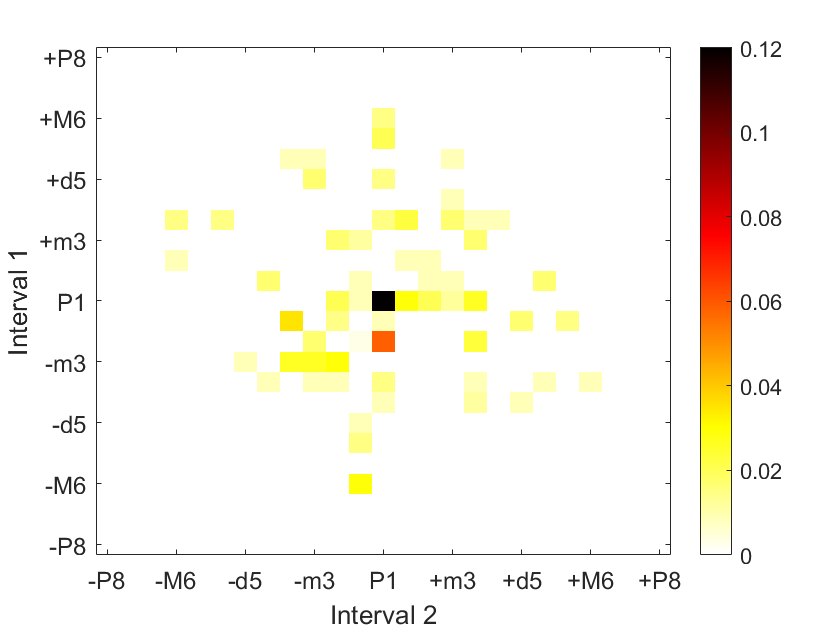

figure; plotdist(ivdist2(vln1),'hot'); 

## Analysis

### tonality

#### keymode

What's the mode of the Haydn excerpt?

mode = keymode(vln1)

mode = 1

#### kkkey & kkcc

According to the model, it's in the major mode. Let's use the 'kkcc' algorithm to determine the key of the excerpt. It will output a 24-element vector representing the 24 major and minor keys, starting with C major.

key = keyname(kkkey(vln1))

key = 1×1 cell array
    {'B'}


Let's look at the distribution of correlations for all 24 major and minor keys.

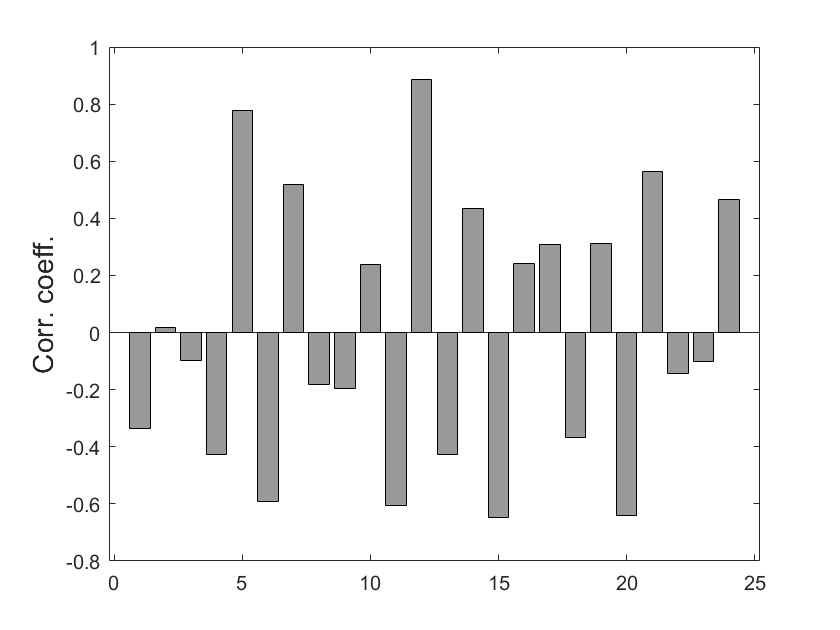

plotdist(kkcc(vln1));

#### keysom

Let's look at these distributions using a self-organizing map.

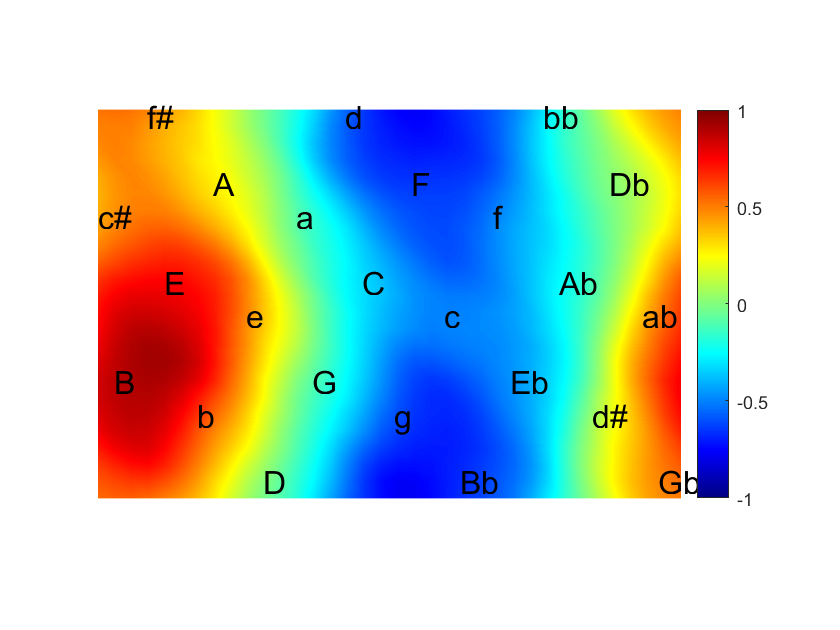

figure; keysom(vln1);

#### keysomanim

The problem with looking at the whole sonata-form exposition is that we're looking at the PC distribution across two keys! Let's animate how the SOM changes using a windowed analysis of the PC distribution.

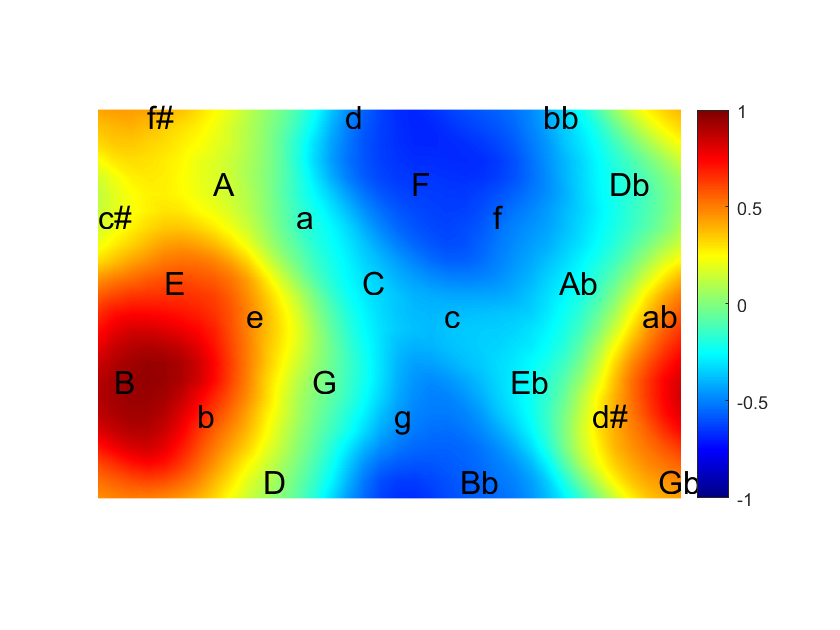

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in title (line 80)
   h = get(ax,'Title');

Error in keysomanim (

figure; keysomanim(haydn);

### Rhythm & Segmentation

#### boundary

Let's find all of the rhythmic boundaries in the first violin part.

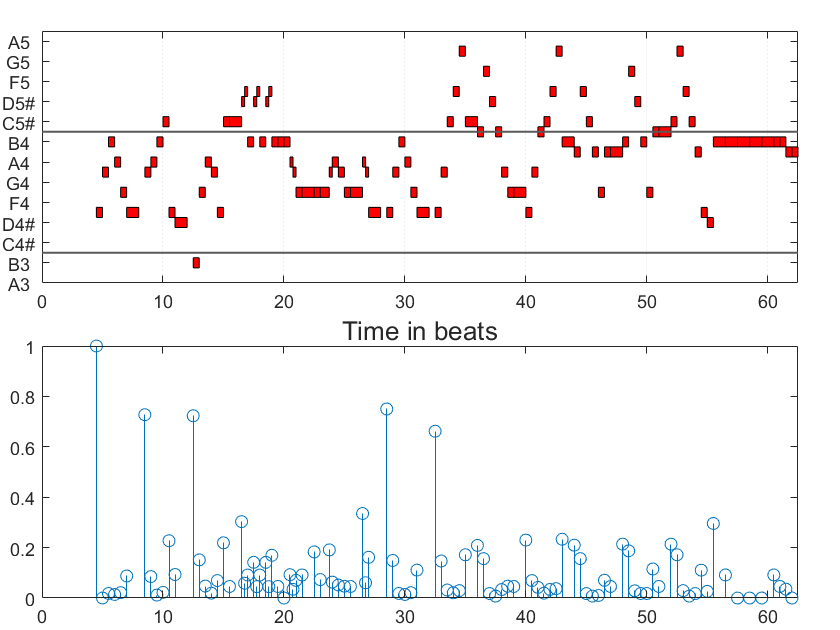

boundary(vln1,'fig');

#### Shepard illusion

playsound(createnmat([48:96],.5),'shepard');

204K samples


#### Moving windows

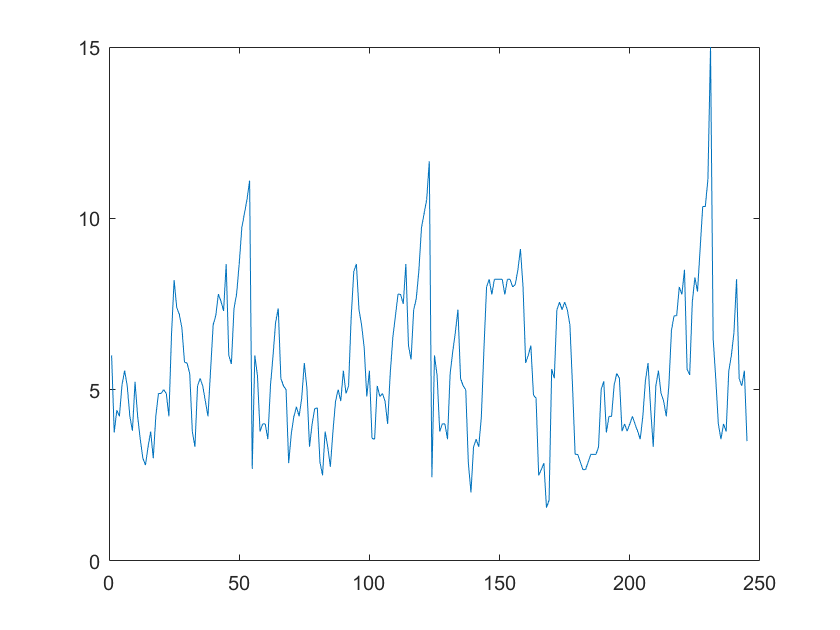

dens = movewindow(haydn,3,1.5,'sec','notedensity');
figure; plot(dens)